% 2022.07.19 - Gain test visualization

clear all
gain_test_results_default(1) = load('gain_test_results\5LinkWalkingOpenOCL2022-11-13-10-58.mat'); % unevenground_0_1_v2_7, k_bar_ba = 0
gain_test_results_default(2) = load('gain_test_results\5LinkWalkingOpenOCL2022-11-15-16-59.mat'); % unevenground_0_1_v2_12, k_bar_ba = 0
gain_test_results_default(3) = load('gain_test_results\5LinkWalkingOpenOCL2022-10-13-18-05.mat'); % unevenground_0_1_v2_13, k_bar_ba = 0
gain_test_results_default(4) = load('gain_test_results\5LinkWalkingOpenOCL2022-10-16-10-19.mat'); % unevenground_0_1_v2_15, k_bar_ba = 0

% check if all gain_test_results_default is defult model
for i = 1:length(gain_test_results_default)
    assert(gain_test_results_default(i).gain_test_result.params.k_ba == 0)
end

gain_test_results_BA(1) = load('gain_test_results\5LinkWalkingOpenOCL2022-09-27-22-47.mat'); % unevenground_0_1_v2_7, k_bar_ba != 0
gain_test_results_BA(2) = load('gain_test_results\5LinkWalkingOpenOCL2022-10-13-18-37.mat'); % unevenground_0_1_v2_12, k_bar_ba != 0
gain_test_results_BA(3) = load('gain_test_results\5LinkWalkingOpenOCL2022-11-20-12-37.mat'); % unevenground_0_1_v2_13, k_bar_ba != 0
gain_test_results_BA(4) = load('gain_test_results\5LinkWalkingOpenOCL2022-11-28-13-37.mat'); % unevenground_0_1_v2_15, k_bar_ba != 0


for i = 1:length(gain_test_results_default)
    assert(gain_test_results_default(i).gain_test_result.params.k_ba == 0) % check if all gain_test_results_default is defult model
    assert(mean(size(gain_test_results_default(i).gain_test_result.PASS) == [100, 26]))
end

for i = 1:length(gain_test_results_BA)
    assert(gain_test_results_BA(i).gain_test_result.params.k_ba ~= 0) % check if all gain_test_results_BA is BA model
    assert(mean(size(gain_test_results_BA(i).gain_test_result.PASS) == [100, 26]))
end


## averaging the results

PASS_sum_default = zeros(100, 26);
for i = 1:length(gain_test_results_default)
    PASS_sum_default = PASS_sum_default + gain_test_results_default(i).gain_test_result.PASS;
end
PASS_average_default = PASS_sum_default./length(gain_test_results_default);

PASS_sum_BA = zeros(100, 26);
for i = 1:length(gain_test_results_BA)
    PASS_sum_BA = PASS_sum_BA + gain_test_results_BA(i).gain_test_result.PASS;
end
PASS_average_BA = PASS_sum_BA./length(gain_test_results_default);

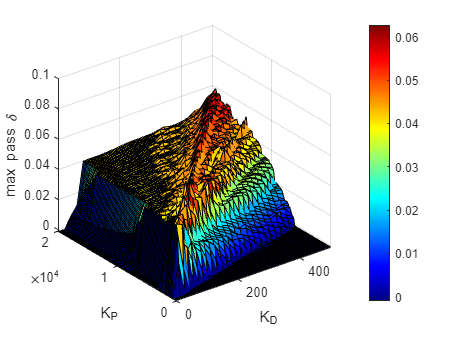

% default
def_x = gain_test_results_default(1).gain_test_result.gains_KD;
def_y = gain_test_results_default(1).gain_test_result.gains_KP;
def_PASS = PASS_average_default;

size_def = size(def_PASS);

figure()
surf(def_x, def_y(1:size_def(1)), def_PASS)
colormap jet
colorbar

% caxis([-0.001 max(max(gain_test_results_BA.gain_test_result.PASS))])

xlabel('K_D')
ylabel('K_P')
zlabel('max pass \delta')
zlim([-0.001,0.1])
xlim([0,500])

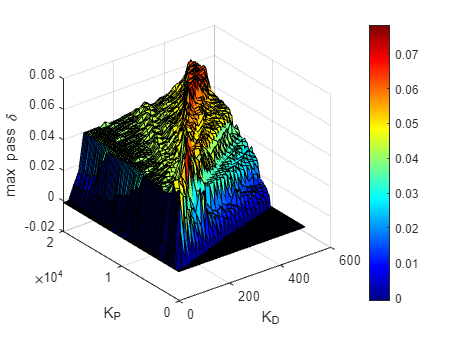

% BA
BA_x = gain_test_results_BA(1).gain_test_result.gains_KD;
BA_y = gain_test_results_BA(1).gain_test_result.gains_KP;
BA_PASS = PASS_average_BA;

size_BA = size(BA_PASS);

figure()
surf(BA_x, BA_y(1:size_BA(1)), BA_PASS)
% hold on
% plot3(20, 2000, 0.066)
colormap jet
colorbar

% caxis([-0.001 max(max(BA_PASS))])

xlabel('K_D')
ylabel('K_P')
zlabel('max pass \delta')

% zlim([-0.001,0.1])
% xlim([0,500])


## Plot the difference

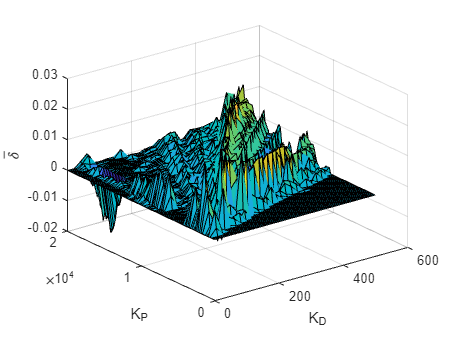

PASS_diff = BA_PASS - def_PASS;
figure()
surf(BA_x, BA_y(1:size_BA(1)), PASS_diff)
xlabel('K_D')
ylabel('K_P')
zlabel('$\bar{\delta}$',Interpreter='latex')

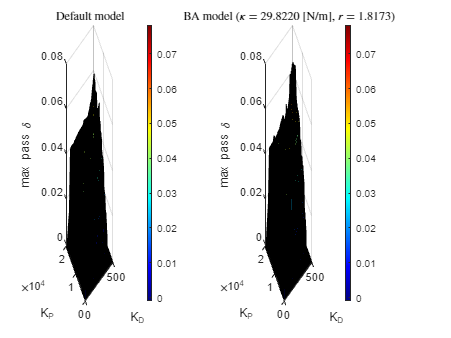

% plot side-by-side

figure()

subplot(1,2,1)
surf(def_x, def_y(1:size_def(1)), def_PASS)
colormap jet
colorbar

xlabel('K_D')
ylabel('K_P')
zlabel('max pass \delta')
zlim([-0.001,0.08])
xlim([0,500])

caxis([-0.001 max(max(BA_PASS))])
view([-35 20])
title('Default model', Interpreter='latex')

subplot(1,2,2)
surf(BA_x, BA_y(1:size_BA(1)), BA_PASS)
colormap jet
colorbar

xlabel('K_D')
ylabel('K_P')
zlabel('max pass \delta')
zlim([-0.001,0.08])
xlim([0,500])

caxis([-0.001 max(max(BA_PASS))])
view([-35 20])
title('BA model ($\kappa = 29.8220$ [N/m], $r = 1.8173$)', Interpreter='latex')